clear all
clc


**OBS: A diferença da versão 2 para a versão 1 é que aqui é considerado o tempo do descarregamento devido às perdas (p_leak) que não foi considerado no caso anterior. Este script e as figuras geradas corrigem essa diferença de tempo.**

## **Comparação entre o modelo belga e o modelo proposto**

Cálculos de Cmin, Tcharge e Minimal Interval para a tecnologia LoRaWAN - SODAQ Explorer off idle

%Parâmetros do sistema
Pharv = 1e-6*[58:1:1e3];
%Pharv = 1e-3*[0.1];
Payload = 20;
e_sense = 0.05;
t_sense = 0.01;
v_max = 4.5;
v_min = 2.8;
 
%Parâmetros de especificação do LoRaWAN - SODAQ Explorer off idle
pream = 8; 
bw = 125000;
sf = 7;
maxpl = 51; 
cr = 0.8;
ih = 1;
de = 0;
p_tx = 0.134;
e_rx = 0.166;
t_rx = 2.2;
e_setup = 0.456;
t_setup = 13;
p_idle = 0.00000108;
 
s_tx = pream+4.25+8+max(ceil((8*Payload-4*sf+44-20*ih)/(4*(sf-2*de)))*(cr+4),0); % equação (9)
t_tx = s_tx*(sf^2/bw); % equação (10) 
pmu_l = 1/1.2;
e_peak = (e_sense + e_setup + e_rx + t_tx*p_tx); % equação (11)
t_peak = t_setup + t_rx + t_tx + t_sense; % baseada na equação (12)
i_leak = 10e-6;
p_leak = 45e-6; 
cmin = (2*(e_peak/pmu_l + p_leak*t_peak))/(v_max^2 - v_min^2); %equação (5) do paper belga. Obs: para LoRaWAN sem pmu_l
p_cons = p_idle/pmu_l + p_leak; %equação (7) do paper belga
pmu_h = 0.8;
p_harv = pmu_h*Pharv; %equação (1) do paper belga
  
for i = 1:length(p_harv)
t_charge(i) = - ((v_max^2)/p_cons) * cmin * log((v_max - (v_max*p_harv(i))/p_cons)/(v_min - (v_max*p_harv(i))/p_cons)); %equação (8) do paper belga
end
t_charge = t_charge;
 
% min_interval = t_charge + t_peak %equação (6) do paper belga
 
%cálculos usando as equações do modelo proposto
 
for i=1:length(p_harv)
twet25(i) = (cmin*(0.25*v_max)^2)/(2*Pharv(i));
taoc25(i) = -twet25(i)/log(1 - (0.25*v_max)/v_max);
twet50(i) = (cmin*(0.50*v_max)^2)/(2*Pharv(i));
taoc50(i) = -twet50(i)/log(1 - (0.50*v_max)/v_max);
twet75(i) = (cmin*(0.75*v_max)^2)/(2*Pharv(i));
taoc75(i) = -twet75(i)/log(1 - (0.75*v_max)/v_max);
taoc_avg(i) = mean([taoc25(i) taoc50(i) taoc75(i)]);
twet_ini(i) = -taoc_avg(i)*log(1 - (0.9999*v_max)/v_max); % cálculo do twet inicial
twet_caso1(i) = taoc_avg(i)*log(1 - v_min/v_max) + twet_ini(i); % caso s1 = 1 e s2 = 0 método 1
twet_caso2(i) = -taoc_avg(i)*log((v_max - 0.9999*v_max)/(v_max - v_min)); % caso s1 = 1 e s2 = 0 método 2
 
end
 
carregamento = twet_caso2;
 
%esr + Req2k2 = res
res = (v_max - v_min - (i_leak*t_peak)/cmin)/i_leak % resistência equivalente do circuito após o supercap

res = 1.6988e+05

descarregamento = (v_max - v_min)*cmin/i_leak -cmin*res;
min_interval_2 = descarregamento + carregamento + t_peak % caso s1 = 1 e s2 = 1

min_interval_2 = 	1.0e+04 *

    6.1591    6.0548    5.9539    5.8564    5.7620    5.6705    5.5820    5.4962    5.4129    5.3322    5.2538    5.1777    5.1038    5.0319    4.9621    4.8942    4.8281    4.7637    4.7011    4.6401    4.5806    4.5227    4.4662    4.4111    4.3573    4.3049    4.2537    4.2037    4.1548    4.1071    4.0605    4.0149    3.9703    3.9267    3.8840    3.8423    3.8015    3.7615    3.7223    3.6840    3.6464    3.6096    3.5736    3.5382    3.5036    3.4696    3.4362    3.4035    3.3715    3.3400


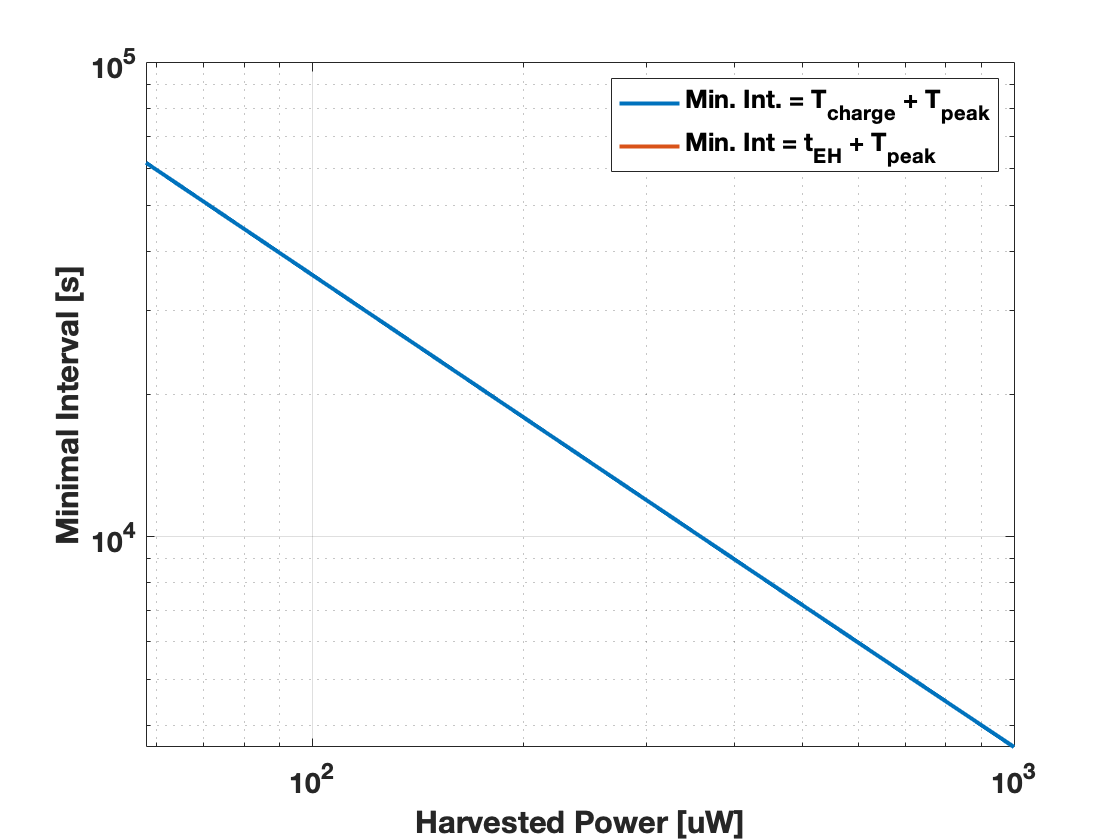


figure(1)
loglog(Pharv*1e6,min_interval_2,"LineWidth",2)
grid on
hold on
loglog(Pharv*1e6,min_interval_2,"LineWidth",2)
legend('Min. Int. = T_c_h_a_r_g_e + T_p_e_a_k','Min. Int = t_E_H + T_p_e_a_k')
xlabel('Harvested Power [uW]')
ylabel('Minimal Interval [s]')
set(gca,'FontSize',14,'FontWeight','bold')

Cálculos de Cmin, Tcharge e Minimal Interval para a tecnologia BLE

%Parâmetros do sistema
Pharv = 1e-6*[80.5:0.5:1e3];
%Pharv = 1e-3*[1];
Payload = 20;
e_sense = 0.05;
t_sense = 0.01;
v_max = 4.5;
v_min = 2.8;
R = 100000;
 
Ttx_d = (8*(Payload + 18))/R; %equação (15) do paper belga
e_sense_tx = e_sense + 6.2e-6 + 16.4e-3*(3*Ttx_d);  %equação (16) do paper belga
Ttx_p = (8*(19 + 18))/R; %equação (15) do paper belga, mas usado valor 19 no lugar de payload
Trd = 0.255;
Trw = 0.255;
e_poll = 28.2e-6 + 16.4e-3*(3*Ttx_p) + 16.1e-6*Trd + 15.6e-3*Trw; %equação (17) do paper belga
pmu_l = 1/1.2;
e_peak = (e_sense_tx + e_poll); %equação (18) do paper belga
i_leak = 10e-6;
p_leak = 45e-6;
t_peak = t_sense + 0.050039 + Ttx_d*3 + Ttx_p*3 + Trd + Trw; %referência à equação (19) do paper belga
cmin = (2*(e_peak/pmu_l + p_leak*t_peak))/(v_max^2 - v_min^2); %equação (5) do paper belga
p_idle = 16.128e-6;
p_cons = p_idle/pmu_l + p_leak; %equação (7) do paper belga
pmu_h = 0.8;
p_harv = pmu_h*Pharv; %equação (1) do paper belga
 
for i = 1:length(Pharv)
t_charge(i) = - ((v_max^2)/p_cons) * cmin * log((v_max - (v_max*p_harv(i))/p_cons)/(v_min - (v_max*p_harv(i))/p_cons)); %equação (8) do paper belga
end
t_charge = t_charge;
 
min_interval = t_charge + t_peak %equação (6) do paper belga

min_interval = 	1.0e+04 *

    2.0710    1.3278    1.1216    0.9988    0.9119    0.8451    0.7910    0.7459    0.7072    0.6736    0.6438    0.6173    0.5934    0.5717    0.5518    0.5336    0.5167    0.5011    0.4865    0.4729    0.4602    0.4482    0.4369    0.4263    0.4162    0.4066    0.3975    0.3889    0.3807    0.3728    0.3653    0.3581    0.3512    0.3446    0.3383    0.3322    0.3264    0.3207    0.3153    0.3101    0.3050    0.3001    0.2954    0.2909    0.2864    0.2822    0.2780    0.2740    0.2701    0.2663


 
%cálculos usando as equações do modelo proposto
for i = 1:length(Pharv)
twet25(i) = (cmin*(0.25*v_max)^2)/(2*Pharv(i));
taoc25(i) = -twet25(i)/log(1 - (0.25*v_max)/v_max);
twet50(i) = (cmin*(0.50*v_max)^2)/(2*Pharv(i));
taoc50(i) = -twet50(i)/log(1 - (0.50*v_max)/v_max);
twet75(i) = (cmin*(0.75*v_max)^2)/(2*Pharv(i));
taoc75(i) = -twet75(i)/log(1 - (0.75*v_max)/v_max);
taoc_avg(i) = mean([taoc25(i) taoc50(i) taoc75(i)]);
twet_ini(i) = -taoc_avg(i)*log(1 - (0.9999*v_max)/v_max); % cálculo do twet inicial
twet_caso1(i) = taoc_avg(i)*log(1 - v_min/v_max) + twet_ini(i); % caso s1 = 1 e s2 = 0 método 1
twet_caso2(i) = -taoc_avg(i)*log((v_max - 0.9999*v_max)/(v_max - v_min)); % caso s1 = 1 e s2 = 0 método 2
 
end
carregamento = twet_caso2;

% esr + Req2k2 = res
res = (v_max - v_min - (i_leak*t_peak)/cmin)/i_leak % resistência equivalente do circuito após o supercap

res = 1.6994e+05

descarregamento = (v_max - v_min)*cmin/i_leak -cmin*res;
min_interval_2 = descarregamento + carregamento + t_peak % caso s1 = 1 e s2 = 1

min_interval_2 = 	1.0e+03 *

    3.5707    3.5486    3.5269    3.5054    3.4841    3.4632    3.4424    3.4219    3.4017    3.3817    3.3619    3.3424    3.3231    3.3040    3.2851    3.2665    3.2480    3.2298    3.2117    3.1939    3.1763    3.1588    3.1416    3.1245    3.1076    3.0909    3.0744    3.0580    3.0419    3.0259    3.0100    2.9943    2.9788    2.9635    2.9483    2.9333    2.9184    2.9036    2.8891    2.8746    2.8603    2.8462    2.8322    2.8183    2.8045    2.7909    2.7774    2.7641    2.7509    2.7378


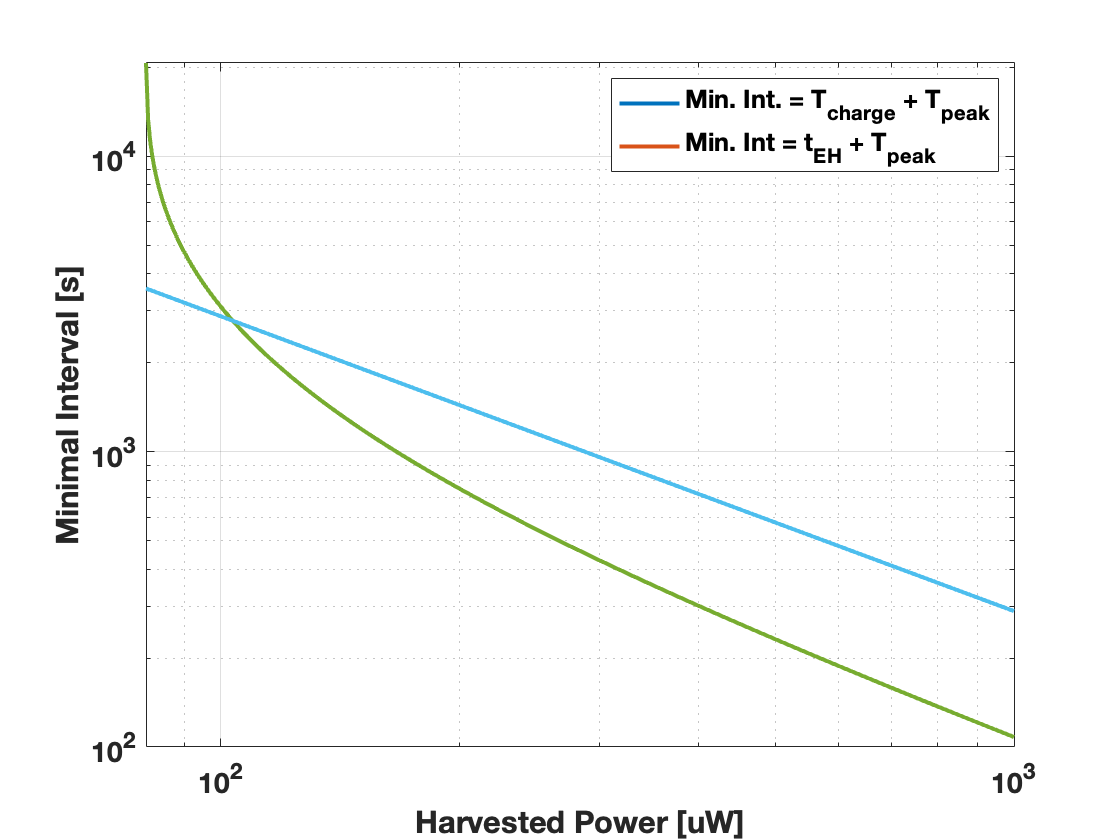


figure(3)
loglog(Pharv*1e6,min_interval,"LineWidth",2)
grid on
hold on
loglog(Pharv*1e6,min_interval_2,"LineWidth",2)
legend('Min. Int. = T_c_h_a_r_g_e + T_p_e_a_k','Min. Int = t_E_H + T_p_e_a_k')
xlabel('Harvested Power [uW]')
ylabel('Minimal Interval [s]')
set(gca,'FontSize',14,'FontWeight','bold')

Cálculos de Cmin, Tcharge e Minimal Interval para a tecnologia 6TiSCH - CC2538

%Parâmetros do sistema
Pharv = 1e-6*[330:1:1e3];
%Pharv = 1e-3*[0.33];
Payload = 20;
e_sense = 0.05;
t_sense = 0.01;
v_max = 4.5;
v_min = 2.8;

nbs = 1;
hops = 1;
t_ts = 0.015;
dao_pl = 96;
eb_pl = 16;
p_tx = 0.000000174;
e_tsoh = 0.0003365;
e_poh = 0.0009706;
p_idle = 0.000180;
overhead = 38; % para hops = 1
e_data = e_sense + e_tsoh + p_tx*(Payload+overhead);
e_dao = e_tsoh + p_tx*p_tx; % porque multiplicar p_tx*p_tx?
e_peak = (e_poh + max(e_data,e_dao));
if e_data>e_dao
    t_peak = 5*t_ts + t_sense;
else
    t_peak = 5*t_ts + 0;
end

i_leak = 10e-6;
p_leak = 45e-6;
pmu_l = 1/1.2;
cmin = (2*(e_peak/pmu_l + p_leak*t_peak))/(v_max^2 - v_min^2); %equação (5) do paper belga
p_cons = p_idle/pmu_l + p_leak; %equação (7) do paper belga
pmu_h = 0.8;
p_harv = pmu_h*Pharv; %equação (1) do paper belga

for i = 1:length(Pharv)
    t_charge(i) = - ((v_max^2)/p_cons) * cmin * log((v_max - (v_max*p_harv(i))/p_cons)/(v_min - (v_max*p_harv(i))/p_cons)); %equação (8) do paper belga
end
t_charge = t_charge;
 
min_interval = t_charge + t_peak %equação (6) do paper belga

min_interval = 	1.0e+03 *

    2.7125    2.5365    2.3954    2.2779    2.1774    2.0898    2.0123    1.9428    1.8801    1.8229    1.7704    1.7219    1.6770    1.6351    1.5959    1.5591    1.5245    1.4919    1.4609    1.4316    1.4038    1.3772    1.3519    1.3277    1.3046    1.2824    1.2611    1.2407    1.2210    1.2021    1.1838    1.1662    1.1493    1.1328    1.1170    1.1016    1.0867    1.0723    1.0583    1.0447    1.0316    1.0188    1.0063    0.9942    0.9824    0.9709    0.9598    0.9489    0.9383    0.9279



%cálculos usando as equações do modelo proposto
for i = 1:length(Pharv)
twet25(i) = (cmin*(0.25*v_max)^2)/(2*Pharv(i));
taoc25(i) = -twet25(i)/log(1 - (0.25*v_max)/v_max);
twet50(i) = (cmin*(0.50*v_max)^2)/(2*Pharv(i));
taoc50(i) = -twet50(i)/log(1 - (0.50*v_max)/v_max);
twet75(i) = (cmin*(0.75*v_max)^2)/(2*Pharv(i));
taoc75(i) = -twet75(i)/log(1 - (0.75*v_max)/v_max);
taoc_avg(i) = mean([taoc25(i) taoc50(i) taoc75(i)]);
twet_ini(i) = -taoc_avg(i)*log(1 - (0.9999*v_max)/v_max); % cálculo do twet inicial
twet_caso1(i) = taoc_avg(i)*log(1 - v_min/v_max) + twet_ini(i); % caso s1 = 1 e s2 = 0 método 1
twet_caso2(i) = -taoc_avg(i)*log((v_max - 0.9999*v_max)/(v_max - v_min)); % caso s1 = 1 e s2 = 0 método 2

end
carregamento = twet_caso2;

% esr + Req2k2 = res
res = (v_max - v_min - (i_leak*t_peak)/cmin)/i_leak; % resistência equivalente do circuito após o supercap
descarregamento = (v_max - v_min)*cmin/i_leak -cmin*res;
min_interval_2 = descarregamento + carregamento + t_peak; % caso s1 = 1 e s2 = 1

figure(3)  
loglog(Pharv*1e6,min_interval,"LineWidth",2) 

Error using loglog
Vectors must be the same length.

grid on 
hold on 
loglog(Pharv*1e6,min_interval_2,"LineWidth",2) 
legend('Min.Int. = T_c_h_a_r_g_e + T_p_e_a_k','Min. Int = t_E_H + T_p_e_a_k') %
xlabel('Harvested Power [uW]') 
ylabel('Minimal Interval [s]') 
set(gca,'FontSize',14,'FontWeight','bold') 